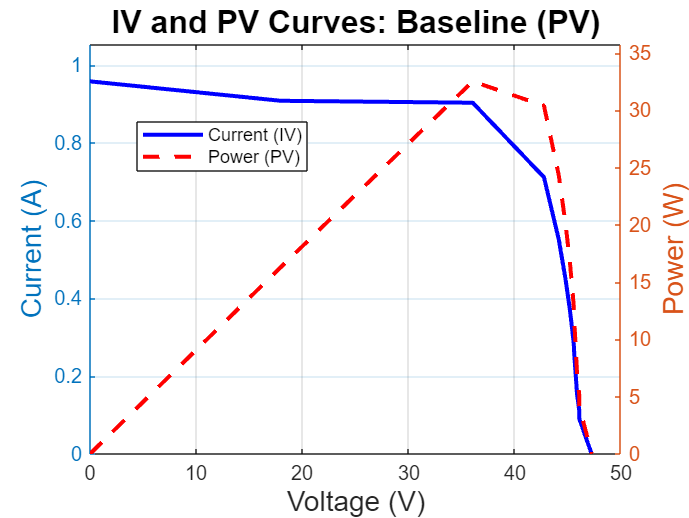

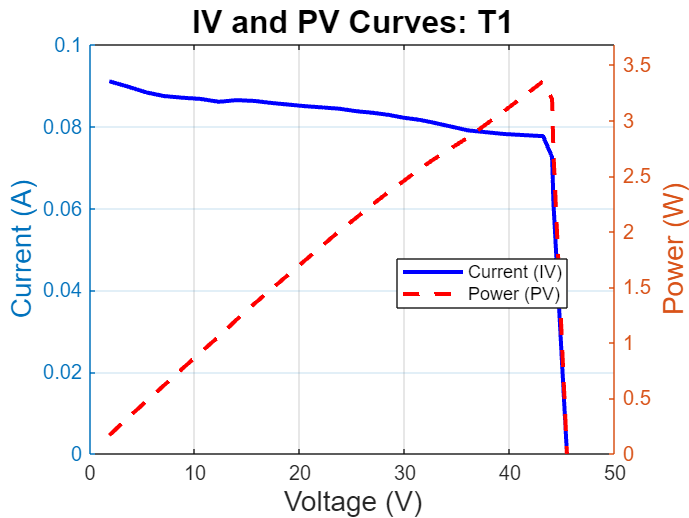

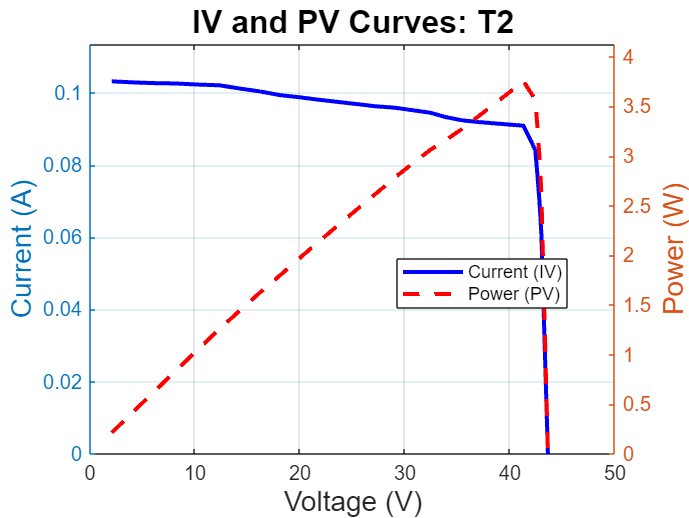

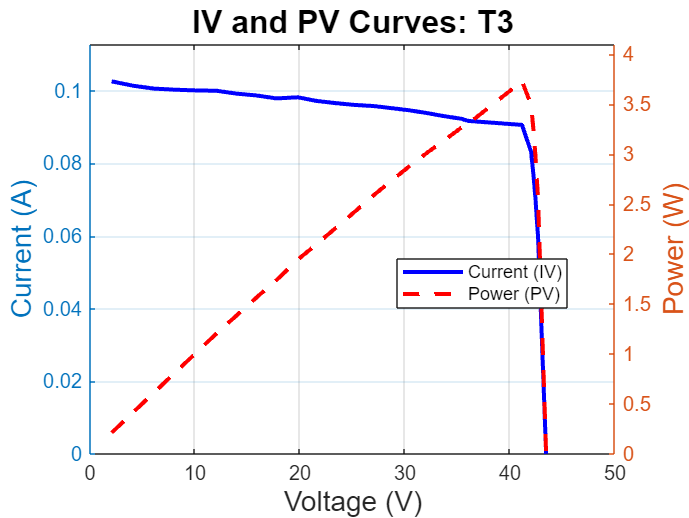

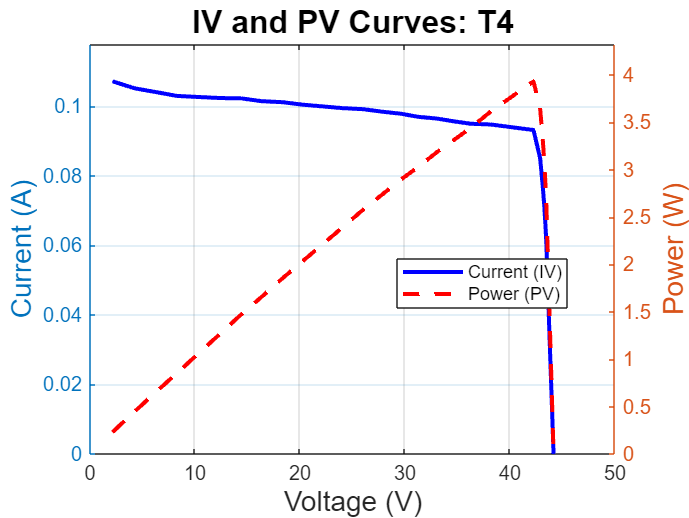

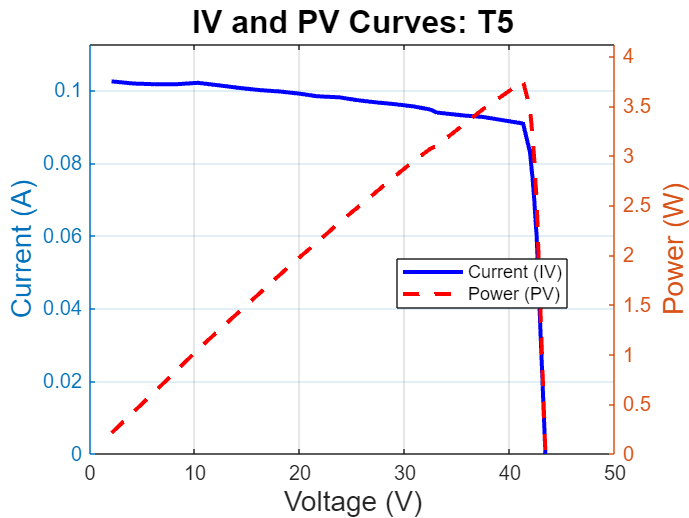

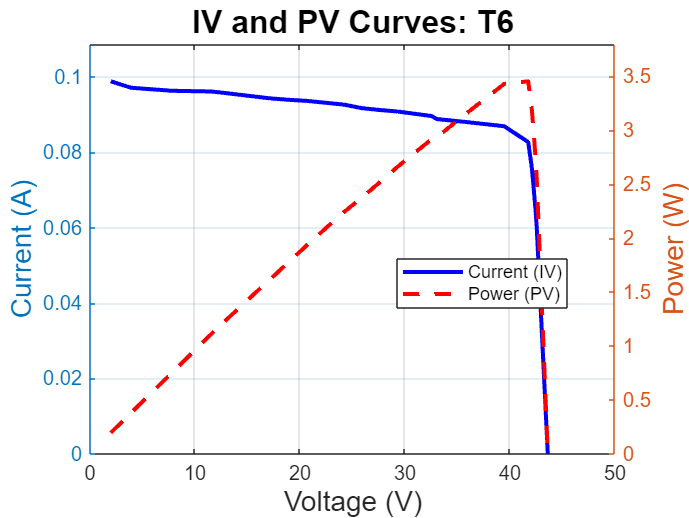

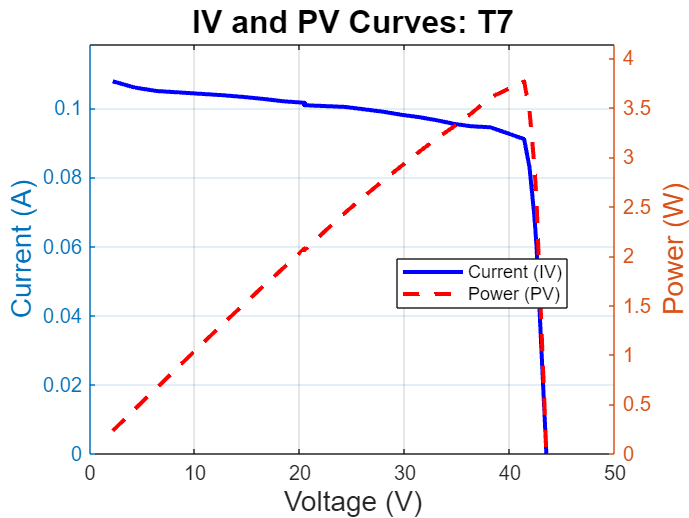

% Get all sheet names
[~, sheetNames] = xlsfinfo('Solar_WPT_Results.xlsx');

% Loop through each sheet
for i = 1:length(sheetNames)
    
    % Read data from the current sheet
    data = readtable('Solar_WPT_Results.xlsx', 'Sheet', sheetNames{i});
    
    % Extract voltage and current
    V = data.Voltage;
    I = data.Current;

    % Compute power
    P = V .* I;

    % Create the figure
    figure;

    % Plot Current (IV curve) on the left y-axis
    yyaxis left;
    plot(V, I, 'b-', 'LineWidth', 2);
    ylabel('Current (A)', 'FontSize', 14);
    ylim([min(I)*1.1, max(I)*1.1]); % optional: adjust limits a bit

    % Plot Power (PV curve) on the right y-axis
    yyaxis right;
    plot(V, P, 'r--', 'LineWidth', 2);
    ylabel('Power (W)', 'FontSize', 14);
    ylim([min(P)*1.1, max(P)*1.1]); % optional: adjust limits a bit

    % Common x-axis
    xlabel('Voltage (V)', 'FontSize', 14);
    title(['IV and PV Curves: ' sheetNames{i}], 'FontSize', 16);
    grid on;
    legend({'Current (IV)', 'Power (PV)'}, 'Location', 'best');
end